## cluster permutation step01

clc;clear;close all;
TFRFolder = 's01_CrossFre';
taskG = {'resting','0back','1back','2back'};
subjG = {'sub-01', 'sub-02', 'sub-03', 'sub-05', 'sub-06', ...
    'sub-07', 'sub-09', 'sub-10', 'sub-11', 'sub-12', ...
    'sub-13', 'sub-14', 'sub-15', 'sub-16', 'sub-17', ...
    'sub-19', 'sub-20', 'sub-21','sub-23','sub-24'};
SaveFolder ='s02_Cluster';
mkdir(SaveFolder);
netG = {'FrontalB','CornorR','SpleniumCorpusC','TemporalB'};
netG_simple = {'FB','CR','SCC','TB'};
load(fullfile(TFRFolder,['fre_label.mat']));

MI_0back_all = cell(numel(netG),numel(netG));
MI_2back_all = cell(numel(netG),numel(netG));
Contacts_WM = cell(numel(netG),1);
FC_all = repmat({cell(1,4)},numel(netG),numel(netG));
for nSub = 1:numel(subjG)
    subjID = subjG{nSub};
    load(fullfile(TFRFolder,subjID,[subjID,'_WM_FC_Alltrials.mat']));
    %%useful channel
    IDX = [];
    %FrontalB 
    IDX{1} = find(strcmpi(wmGoodChans_used(:,2),'InfFrontalB')|strcmpi(wmGoodChans_used(:,2),'MidFrontalB'))';
    Contacts_WM{1,1} = [Contacts_WM{1,1};wmGoodChans_used(IDX{1},[1,2,4])];  
    %CornorR
    IDX{2} = find(strcmpi(wmGoodChans_used(:,2),'AntCoronaR')|strcmpi(wmGoodChans_used(:,2),'SupCoronaR'))';
    Contacts_WM{2,1} = [Contacts_WM{2,1};wmGoodChans_used(IDX{2},[1,2,4])];  
    %SpleniumCorpusC
    IDX{3} = find(strcmpi(wmGoodChans_used(:,2),'SupParietalB')|strcmpi(wmGoodChans_used(:,2),'SpleniumCorpusC'))';
    Contacts_WM{3,1} = [Contacts_WM{3,1};wmGoodChans_used(IDX{3},[1,2,4])];
    %TemporalB
    IDX{4} = find(strcmpi(wmGoodChans_used(:,2),'TemporalB'))';
    Contacts_WM{4,1} = [Contacts_WM{4,1};wmGoodChans_used(IDX{4},[1,2,4])];
     

    FCspearman = FCspearman_whole;
    for net1 = 1:numel(netG)
        for net2 = 1:numel(netG)
            idx1 = IDX{net1};
            idx2 = IDX{net2};
            if ~isempty(idx1) & ~isempty(idx2)
                    mi_0back = FCspearman{1,2}(:,:,idx1,idx2);  
                    mi_0back = reshape(mi_0back,size(mi_0back,1),size(mi_0back,2),[]); mi_0back = permute(mi_0back, [3, 2, 1]);
                    MI_0back_all{net1,net2} = [MI_0back_all{net1,net2};mi_0back]; %clear mi_0back

                    mi_2back = FCspearman{1,4}(:,:,idx1,idx2);  
                    mi_2back = reshape(mi_2back,size(mi_2back,1),size(mi_2back,2),[]); mi_2back = permute(mi_2back, [3, 2, 1]);
                    MI_2back_all{net1,net2} = [MI_2back_all{net1,net2};mi_2back]; %clear mi_2back
            end
        end
    end
end
clear FC FCspearman;
save(fullfile(SaveFolder,['MI_all_noatanh.mat']),'MI_0back_all', 'MI_2back_all');

## %guard band for spurious coupling artifacts (30±5Hz)_test

% clc;clear;close all;
% load('MI_all_noatanh.mat');
% load('fre_label.mat')
% t0 = cellfun(@(x) squeeze(mean(x,1,'omitnan')),MI_0back_all,'UniformOutput',false);
% t2 = cellfun(@(x) squeeze(mean(x,1,'omitnan')),MI_2back_all,'UniformOutput',false);
% netG = {'FrontalB','CR','SpleniumCorpusC','TemporalB'};
% figure('Units', 'inches', 'Position', [0 0 8.27 2.6]);
% subplot(1,2,1); imagesc(t0{4,1}); axis xy; colormap jet; colorbar;
% xline([17,37,46], 'LineWidth', 2, 'LineStyle', '--', 'Color', [1 1 1]);
% xticks([1 17 37 46 54]); xticklabels(fre_label([1 17 37 46 54],1)); xlabel({netG{4}});
% yline([10,41], 'LineWidth', 2, 'LineStyle', '--', 'Color', [1 1 1]);
% yticks([1 10 41 91]); yticklabels(fre_label([1 10 41 91]+53,1)); ylabel({netG{1}});
% set(gca, 'FontName', 'Arial', 'FontSize', 10, 'LineWidth', 2);
% title('0-back', 'FontName', 'Arial', 'FontSize', 10);
% 
% subplot(1,2,2); imagesc(t2{4,1}); axis xy; colormap jet; colorbar;
% xline([17,37,46], 'LineWidth', 2, 'LineStyle', '--', 'Color', [1 1 1]);
% xticks([1 17 37 46 54]); xticklabels(fre_label([1 17 37 46 54],1)); xlabel({netG{4}});
% yline([10,41], 'LineWidth', 2, 'LineStyle', '--', 'Color', [1 1 1]);
% yticks([1 10 41 91]); yticklabels(fre_label([1 10 41 91]+53,1)); ylabel({netG{1}});
% set(gca, 'FontName', 'Arial', 'FontSize', 10, 'LineWidth', 2);
% title('2-back', 'FontName', 'Arial', 'FontSize', 10);

## cluster permutation step02

clc;clear;close all;
addpath(genpath('github_replication/function'));
TFRFolder = 's01_CrossFre';
SaveFolder ='s02_Cluster';
load(fullfile(TFRFolder,['fre_label.mat']));
load(fullfile(SaveFolder,['MI_all_noatanh.mat']));
MI_0back_all = cellfun(@(x) x(:,6:91,1:49),MI_0back_all,'UniformOutput',false); %±5Hz
MI_2back_all = cellfun(@(x) x(:,6:91,1:49),MI_2back_all,'UniformOutput',false);

netG = {'FrontalB','CornorR','SpleniumCorpusC','TemporalB'};
netG_simple = {'FB','CR','SCC','TB'};
N = 0;

%IDX={[1,1],[1,3],[4,1],[4,3]};%fig4
%IDX = {[1,4],[3,1],[3,3],[3,4],[4,4]};%supplementary figs5
IDX = {[1,1],[1,3],[4,1],[4,3],[1,4],[3,1],[3,3],[3,4],[4,4]};%merge
for idx = 1:numel(IDX)
    i = IDX{idx}(1);
    j = IDX{idx}(2);
    disp(['Num-',num2str(idx),' net-',num2str(i),' vs. net-',num2str(j)]);
    N = N+1;
    MI_0back = MI_0back_all{i,j}; MI_0back = permute(MI_0back,[2,3,1]); %fre1,fre2,fc_pair_num
    MI_2back = MI_2back_all{i,j}; MI_2back = permute(MI_2back,[2,3,1]);
    [t_orig, p_orig, clust_info] = TFR_clusterPermTest_pairTtest(MI_2back, MI_0back, 1000, 0.01);
    save(fullfile(SaveFolder,['net_',num2str(i),'-',num2str(j),'_001.mat']),'t_orig','p_orig','clust_info','-v7.3');
end

Num-1 net-1 vs. net-1


Permutation Num is 7
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 6
Permutation Num is 13
Permutation Num is 20
Permutation Num is 27
Permutation Num is 34
Permutation Num is 41
Permutation Num is 48
Permutation Num is 55
Permutation Num is 5
Permutation Num is 12
Permutation Num is 19
Permutation Num is 26
Permutation Num is 33
Permutation Num is 47
Permutation Num is 54
Permutation Num is 4
Permutation Num is 11
Permutation Num is 18
Permutation Num is 25
Permutation Num is 32
Permutation Num is 40
Permutation Num is 39
Permutation Num is 46
Permutation Num is 53
Permutation Num is 3
Permutation Num is 10
Permutation Num is 17
Permutation Num is 24
Permutation Num is 31
Permutation Num is 38
Permutation Num is 45
Permutation Num is 52
Permutation Num is 2
Permutation Num is 16
Permutation Num is 23
Permutation Num is 30
Permutation Num is 37
Permutation Num 

Num-2 net-1 vs. net-3


Permutation Num is 7
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 6
Permutation Num is 5
Permutation Num is 13
Permutation Num is 12
Permutation Num is 20
Permutation Num is 19
Permutation Num is 27
Permutation Num is 26
Permutation Num is 34
Permutation Num is 33
Permutation Num is 41
Permutation Num is 40
Permutation Num is 48
Permutation Num is 47
Permutation Num is 55
Permutation Num is 54
Permutation Num is 4
Permutation Num is 3
Permutation Num is 11
Permutation Num is 10
Permutation Num is 18
Permutation Num is 17
Permutation Num is 25
Permutation Num is 24
Permutation Num is 32
Permutation Num is 31
Permutation Num is 39
Permutation Num is 38
Permutation Num is 46
Permutation Num is 45
Permutation Num is 53
Permutation Num is 52
Permutation Num is 2
Permutation Num is 1
Permutation Num is 9
Permutation Num is 8
Permutation Num is 16
Permutation Num is 

Num-3 net-4 vs. net-1


Permutation Num is 7
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 6
Permutation Num is 13
Permutation Num is 20
Permutation Num is 27
Permutation Num is 34
Permutation Num is 41
Permutation Num is 48
Permutation Num is 55
Permutation Num is 12
Permutation Num is 19
Permutation Num is 26
Permutation Num is 33
Permutation Num is 54
Permutation Num is 5
Permutation Num is 4
Permutation Num is 11
Permutation Num is 18
Permutation Num is 25
Permutation Num is 32
Permutation Num is 40
Permutation Num is 39
Permutation Num is 47
Permutation Num is 46
Permutation Num is 53
Permutation Num is 3
Permutation Num is 10
Permutation Num is 17
Permutation Num is 24
Permutation Num is 31
Permutation Num is 38
Permutation Num is 45
Permutation Num is 52
Permutation Num is 2
Permutation Num is 9
Permutation Num is 16
Permutation Num is 23
Permutation Num is 30
Permutation Num i

Num-4 net-4 vs. net-3


Permutation Num is 7
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 13
Permutation Num is 20
Permutation Num is 27
Permutation Num is 41
Permutation Num is 40
Permutation Num is 48
Permutation Num is 55
Permutation Num is 6
Permutation Num is 5
Permutation Num is 12
Permutation Num is 19
Permutation Num is 26
Permutation Num is 34
Permutation Num is 33
Permutation Num is 47
Permutation Num is 54
Permutation Num is 4
Permutation Num is 3
Permutation Num is 11
Permutation Num is 10
Permutation Num is 18
Permutation Num is 17
Permutation Num is 32
Permutation Num is 31
Permutation Num is 39
Permutation Num is 38
Permutation Num is 46
Permutation Num is 45
Permutation Num is 53
Permutation Num is 52
Permutation Num is 25
Permutation Num is 24
Permutation Num is 30
Permutation Num is 44
Permutation Num is 2
Permutation Num is 1
Permutation Num is 9
Permutation Num is

Num-5 net-1 vs. net-4


Permutation Num is 7
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 6
Permutation Num is 13
Permutation Num is 20
Permutation Num is 27
Permutation Num is 34
Permutation Num is 41
Permutation Num is 48
Permutation Num is 55
Permutation Num is 5
Permutation Num is 12
Permutation Num is 19
Permutation Num is 26
Permutation Num is 33
Permutation Num is 40
Permutation Num is 4
Permutation Num is 11
Permutation Num is 18
Permutation Num is 39
Permutation Num is 47
Permutation Num is 46
Permutation Num is 54
Permutation Num is 53
Permutation Num is 3
Permutation Num is 10
Permutation Num is 17
Permutation Num is 25
Permutation Num is 24
Permutation Num is 32
Permutation Num is 31
Permutation Num is 38
Permutation Num is 45
Permutation Num is 52
Permutation Num is 2
Permutation Num is 9
Permutation Num is 16
Permutation Num is 23
Permutation Num is 30
Permutation Num i

Num-6 net-3 vs. net-1


Permutation Num is 7
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 27
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 6
Permutation Num is 5
Permutation Num is 13
Permutation Num is 12
Permutation Num is 20
Permutation Num is 19
Permutation Num is 34
Permutation Num is 33
Permutation Num is 41
Permutation Num is 40
Permutation Num is 48
Permutation Num is 47
Permutation Num is 55
Permutation Num is 54
Permutation Num is 26
Permutation Num is 25
Permutation Num is 4
Permutation Num is 3
Permutation Num is 11
Permutation Num is 10
Permutation Num is 18
Permutation Num is 17
Permutation Num is 32
Permutation Num is 31
Permutation Num is 39
Permutation Num is 38
Permutation Num is 46
Permutation Num is 45
Permutation Num is 53
Permutation Num is 52
Permutation Num is 2
Permutation Num is 1
Permutation Num is 9
Permutation Num is 8
Permutation Num is 16
Permutation Num is 15
Permutation Num is 

Num-7 net-3 vs. net-3


Permutation Num is 7
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 6
Permutation Num is 5
Permutation Num is 13
Permutation Num is 20
Permutation Num is 27
Permutation Num is 34
Permutation Num is 41
Permutation Num is 48
Permutation Num is 55
Permutation Num is 19
Permutation Num is 26
Permutation Num is 33
Permutation Num is 40
Permutation Num is 47
Permutation Num is 4
Permutation Num is 3
Permutation Num is 12
Permutation Num is 11
Permutation Num is 18
Permutation Num is 25
Permutation Num is 32
Permutation Num is 46
Permutation Num is 54
Permutation Num is 53
Permutation Num is 2
Permutation Num is 10
Permutation Num is 17
Permutation Num is 24
Permutation Num is 31
Permutation Num is 39
Permutation Num is 38
Permutation Num is 9
Permutation Num is 16
Permutation Num is 23
Permutation Num is 30
Permutation Num is 37
Permutation Num is 45
Permutation Num i

Num-8 net-3 vs. net-4


Permutation Num is 7
Permutation Num is 6
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 13
Permutation Num is 12
Permutation Num is 20
Permutation Num is 19
Permutation Num is 27
Permutation Num is 26
Permutation Num is 34
Permutation Num is 33
Permutation Num is 41
Permutation Num is 40
Permutation Num is 48
Permutation Num is 47
Permutation Num is 55
Permutation Num is 54
Permutation Num is 5
Permutation Num is 4
Permutation Num is 11
Permutation Num is 18
Permutation Num is 3
Permutation Num is 10
Permutation Num is 25
Permutation Num is 24
Permutation Num is 32
Permutation Num is 31
Permutation Num is 39
Permutation Num is 38
Permutation Num is 46
Permutation Num is 45
Permutation Num is 53
Permutation Num is 52
Permutation Num is 17
Permutation Num is 16
Permutation Num is 30
Permutation Num is 37
Permutation Num is 51
Permutation Num is 2
Permutation Num 

Num-9 net-4 vs. net-4


Permutation Num is 7
Permutation Num is 14
Permutation Num is 21
Permutation Num is 28
Permutation Num is 35
Permutation Num is 42
Permutation Num is 49
Permutation Num is 56
Permutation Num is 6
Permutation Num is 13
Permutation Num is 20
Permutation Num is 27
Permutation Num is 34
Permutation Num is 41
Permutation Num is 48
Permutation Num is 55
Permutation Num is 5
Permutation Num is 12
Permutation Num is 19
Permutation Num is 26
Permutation Num is 33
Permutation Num is 40
Permutation Num is 47
Permutation Num is 54
Permutation Num is 4
Permutation Num is 11
Permutation Num is 18
Permutation Num is 25
Permutation Num is 32
Permutation Num is 39
Permutation Num is 46
Permutation Num is 53
Permutation Num is 3
Permutation Num is 10
Permutation Num is 17
Permutation Num is 24
Permutation Num is 31
Permutation Num is 38
Permutation Num is 45
Permutation Num is 52
Permutation Num is 2
Permutation Num is 9
Permutation Num is 23
Permutation Num is 30
Permutation Num is 37
Permutation Num i

## Fig4 ABCD

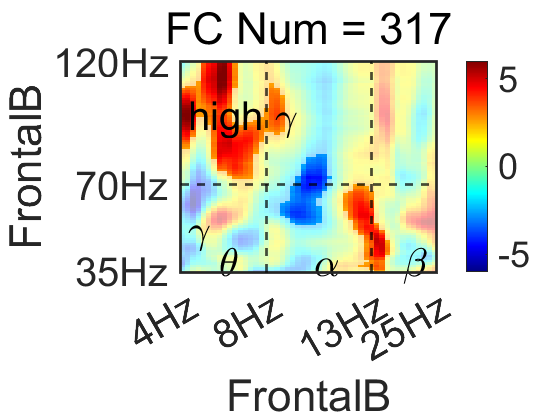

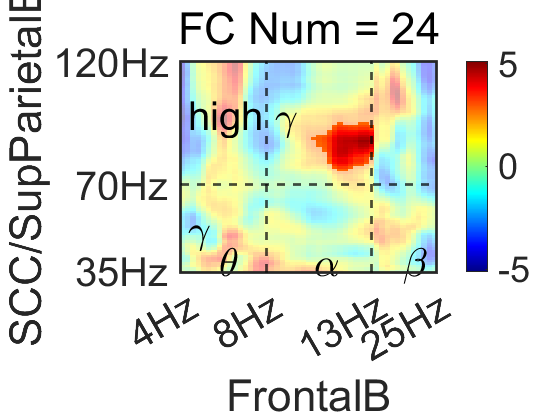

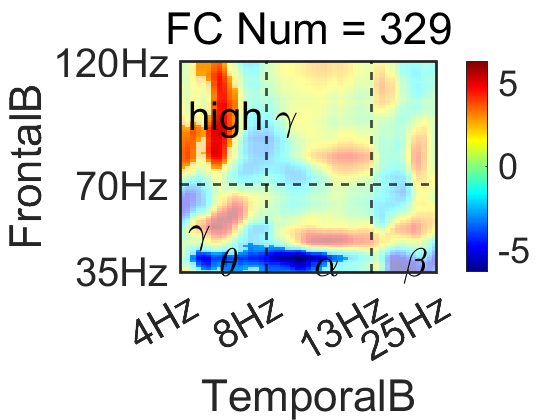

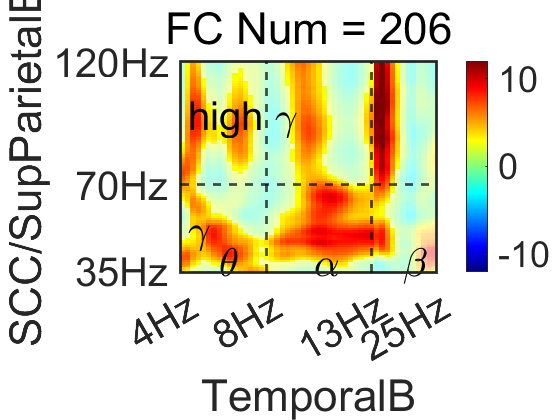

clc;clear;close all;
TFRFolder = 's01_CrossFre';
SaveFolder ='s02_Cluster';
load(fullfile(TFRFolder,['fre_label.mat']));
netG = {'FrontalB','CR','SCC/SupParietalB','TemporalB'};
Num = [317 24 329 206];%FCpair number
P_tr = 0.01;

N = 0;
IDX={[1,1],[1,3],[4,1],[4,3]};
for idx = 1:numel(IDX)
    net1 = IDX{idx}(1);
    net2 = IDX{idx}(2);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    load(fullfile(SaveFolder,['net_',num2str(net1),'-',num2str(net2),'_001.mat']));
    t = t_orig;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % significant postive cluster
    posClusterIds = clust_info.pos_clust_ids;
    posClusterP = clust_info.pos_clust_pval;
    sigIds = find(posClusterP<=P_tr);
    posClusterMask = zeros(size(posClusterIds));
    for n = 1:length(sigIds)
        posClusterMask(posClusterIds==sigIds(n)) = 1;
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % significant negative cluster
    negClusterIds = clust_info.neg_clust_ids;
    negClusterP = clust_info.neg_clust_pval;
    sigIds = find(negClusterP<=P_tr);
    negClusterMask = zeros(size(negClusterIds));
    for n = 1:length(sigIds)
        negClusterMask(negClusterIds==sigIds(n)) = 1;
    end
    ClusterMask = posClusterMask + negClusterMask;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    figure;
    lims = min(abs(min(t(:))), abs(max(t(:))));
    clims = [-lims, lims];
    imagesc(t, clims);
    colorbar;colormap jet; hold on;  
    if idx==4
        caxis([-12 12]);
    end
    xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{net1}});
    yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{net2}}); axis xy; 
    alphaData = ones(size(t));
    alphaData(ClusterMask == 0) = 0.4;
    ax = gca();
    set(ax.Children, 'AlphaData', alphaData);
    set(ax, 'ALim', [0 1]); 
    xline([17,37], 'LineWidth', 2, 'LineStyle', '--', 'Color', [0 0 0]);
    yline([36], 'LineWidth', 2, 'LineStyle', '--', 'Color', [0 0 0]);
    text([8, 26, 43, 2, 2], [5, 5, 5, 18.5, 64.5], ...
        {'\theta', '\alpha', '\beta', '\gamma', 'high \gamma'},  'FontName', 'Arial','FontSize', 30);
    ax = gca();
    ax.TickLength = [0 0]; 
    t = title(['FC Num = ', num2str(Num(idx))], 'FontName', 'Arial',  'FontSize', 30);
    % t.Position(2) = t.Position(2) + 2; 
    set(gca, 'FontName', 'Arial','FontSize', 30, 'LineWidth', 2);
    print(gcf, ['fig4_',num2str(idx),'.png'], '-dpng', '-r600');
end

## supplementary FigureS5

clc;clear;close all;
TFRFolder = 's01_CrossFre';
SaveFolder ='s02_Cluster';
load(fullfile(TFRFolder,['fre_label.mat']));
netG = {'FrontalB','CR','SCC/SupParietalB','TemporalB'};
Num = [329 24 248 206 1163];
P_tr = 0.01;

N = 0;
IDX = {[1,4],[3,1],[3,3],[3,4],[4,4]};%supplementary fig
for idx = 1:numel(IDX)
    net1 = IDX{idx}(1);
    net2 = IDX{idx}(2);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    load(fullfile(SaveFolder,['net_',num2str(net1),'-',num2str(net2),'_001.mat']));
    t = t_orig;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % significant postive cluster
    posClusterIds = clust_info.pos_clust_ids;
    posClusterP = clust_info.pos_clust_pval;
    sigIds = find(posClusterP<P_tr);
    posClusterMask = zeros(size(posClusterIds));
    for n = 1:length(sigIds)
        posClusterMask(posClusterIds==sigIds(n)) = 1;
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % significant negative cluster
    negClusterIds = clust_info.neg_clust_ids;
    negClusterP = clust_info.neg_clust_pval;
    sigIds = find(negClusterP<P_tr);
    negClusterMask = zeros(size(negClusterIds));
    for n = 1:length(sigIds)
        negClusterMask(negClusterIds==sigIds(n)) = 1;
    end
    ClusterMask = posClusterMask + negClusterMask;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    figure;
    lims = min(abs(min(t(:))), abs(max(t(:))));
    clims = [-lims, lims];
    imagesc(t, clims);
    colorbar;colormap jet; hold on;  
    xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{net1}});
    yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{net2}}); axis xy; 
    alphaData = ones(size(t));
    alphaData(ClusterMask == 0) = 0.4;
    ax = gca();
    set(ax.Children, 'AlphaData', alphaData);
    set(ax, 'ALim', [0 1]); 
    xline([17,37], 'LineWidth', 2, 'LineStyle', '--', 'Color', [0 0 0]);
    yline([36], 'LineWidth', 2, 'LineStyle', '--', 'Color', [0 0 0]);
    text([8, 26, 43, 2, 2], [5, 5, 5, 18.5, 64.5], ...
        {'\theta', '\alpha', '\beta', '\gamma', 'high \gamma'},  'FontSize', 30);
    ax = gca();
    ax.TickLength = [0 0];
    t = title(['FC Num = ', num2str(Num(idx))], 'FontName', 'Arial',  'FontSize', 30);
    % t.Position(2) = t.Position(2) + 2; 
    if idx==4
        caxis([-12 12]);
    end
    set(gca, 'FontName', 'Arial','FontSize', 30, 'LineWidth', 2);
    print(gcf, ['fig4S_',num2str(idx),'.png'], '-dpng', '-r600');
end

## Cross-frequency FC Similarity

clc;clear;close all;
TFRFolder = 's01_CrossFre';
SaveFolder ='s02_Cluster';
load(fullfile(TFRFolder,['fre_label.mat']));
load(fullfile(SaveFolder,['MI_all_noatanh.mat']));
MI_0back_all = cellfun(@(x) x(:,6:91,1:49),MI_0back_all,'UniformOutput',false); %±5Hz
MI_2back_all = cellfun(@(x) x(:,6:91,1:49),MI_2back_all,'UniformOutput',false);
netG = {'FrontalB','CornorR','SpleniumCorpusC','TemporalB'};
Num = [317 24 329 206];

t0 = cellfun(@(x) squeeze(mean(x,1,'omitnan')),MI_0back_all,'UniformOutput',false);
t2 = cellfun(@(x) squeeze(mean(x,1,'omitnan')),MI_2back_all,'UniformOutput',false);

figure;
subplot(2,2,1); t = t0{1,1}; lim = max(abs(t(:)));
imagesc(t); colormap jet; colorbar; caxis([-lim lim]); 
xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{1}});
yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{1}}); axis xy; 
xline([17,37], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
yline([36], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 15, 'LineWidth', 2);

subplot(2,2,2); t = t0{1,3}; lim = max(abs(t(:)));
imagesc(t); colormap jet; colorbar; caxis([-lim lim]); 
xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{1}});
yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{3}}); axis xy; 
xline([17,37], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
yline([36], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 15, 'LineWidth', 2);

subplot(2,2,3); t = t0{4,1}; lim = max(abs(t(:)));
imagesc(t); colormap jet; colorbar; caxis([-lim lim]); 
xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{4}});
yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{1}}); axis xy; 
xline([17,37], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
yline([36], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 15, 'LineWidth', 2);

subplot(2,2,4); t = t0{4,3}; lim = max(abs(t(:)));
imagesc(t); colormap jet; colorbar; caxis([-lim lim]); 
xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{4}});
yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{3}}); axis xy; 
xline([17,37], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
yline([36], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 15, 'LineWidth', 2);
sgtitle('0-back','FontWeight','bold', 'FontSize', 18, 'LineWidth', 2)
figure;
subplot(2,2,1); t = t2{1,1}; lim = max(abs(t(:)));
imagesc(t); colormap jet; colorbar; caxis([-lim lim]); 
xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{1}});
yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{1}}); axis xy; 
xline([17,37], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
yline([36], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 15, 'LineWidth', 2);

subplot(2,2,2); t = t2{1,3}; lim = max(abs(t(:)));
imagesc(t); colormap jet; colorbar; caxis([-lim lim]); 
xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{1}});
yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{3}}); axis xy; 
xline([17,37], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
yline([36], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 15, 'LineWidth', 2);

subplot(2,2,3); t = t2{4,1}; lim = max(abs(t(:)));
imagesc(t); colormap jet; colorbar; caxis([-lim lim]); 
xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{4}});
yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{1}}); axis xy; 
xline([17,37], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
yline([36], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 15, 'LineWidth', 2);

subplot(2,2,4); t = t2{4,3}; lim = max(abs(t(:)));
imagesc(t); colormap jet; colorbar; caxis([-lim lim]); 
xticks([1 17 37 49]); xticklabels(fre_label([1 17 37 49],1)); xlabel({netG{4}});
yticks([1 36 86]); yticklabels(fre_label([1 36 86]+58,1)); ylabel({netG{3}}); axis xy; 
xline([17,37], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
yline([36], 'LineWidth', 3, 'LineStyle', '--', 'Color', [0 0 0]);
set(gca, 'FontName', 'Arial','FontWeight','bold', 'FontSize', 15, 'LineWidth', 2);
sgtitle('2-back','FontWeight','bold', 'FontSize', 18, 'LineWidth', 2)
IDX={[1,1],[1,3],[4,1],[4,3]};
for ii = 1:4
    temp0 = t0{IDX{ii}(1),IDX{ii}(2)};
    temp2 = t2{IDX{ii}(1),IDX{ii}(2)};
    [r(ii),p(ii)] = corr(temp0(:),temp2(:),'type','Spearman');
end
format short
r = reshape(r,2,2)'
p = reshape(p,2,2)'
